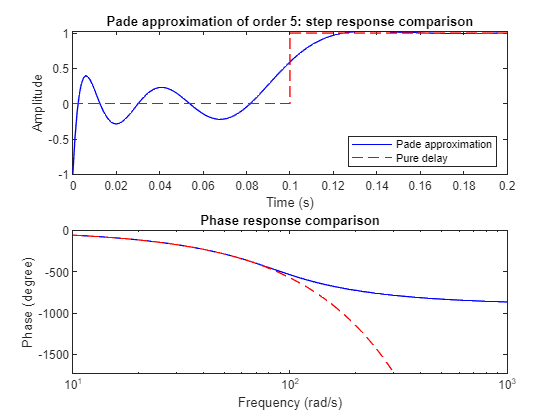

clear

  Gs_Licz=[0 1];
  Gs_Mian=poly([-0.5+1i, -0.5-1i, -1]);
  Gs=tf(Gs_Licz,Gs_Mian);
  %step(Gs)
pade(0.1,5);

Gs;
[Gs2_Licz,Gs2_Mian]=pade(0.5,3);
Gs2=tf(Gs2_Licz,Gs2_Mian);
Gs2=Gs*Gs2;
Gs2;
%step(Gs,Gs2);

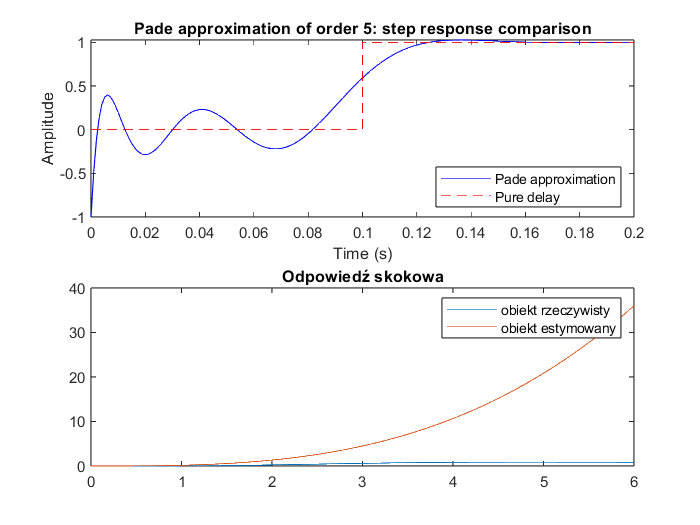

 
 Iteration   Func-count     min f(x)         Procedure
     0            1           103145         
     1            5          93176.4         initial simplex
     2            6          93176.4         reflect
     3            7          93176.4         reflect
     4            9          87087.8         expand
     5           11          77374.8         expand
     6           12          77374.8         reflect
     7           14          66119.2         expand
     8           16            54763         expand
     9           17            54763         reflect
    10           19          41175.9         expand
    11           21          29066.5         expand
    12           22          29066.5         reflect
    13           24          19529.9         expand
    14           26          11218.4         expand
    15           27          11218.4         reflect
    16           29          6440.39         expand
    17           31           3121.1         expan

x0 = [1,0,0,0];

fun = @ident;
options = optimset('Display','iter','PlotFcns',@optimplotfval);
[x,fval,exitflag] = fminsearch(fun,x0,options);

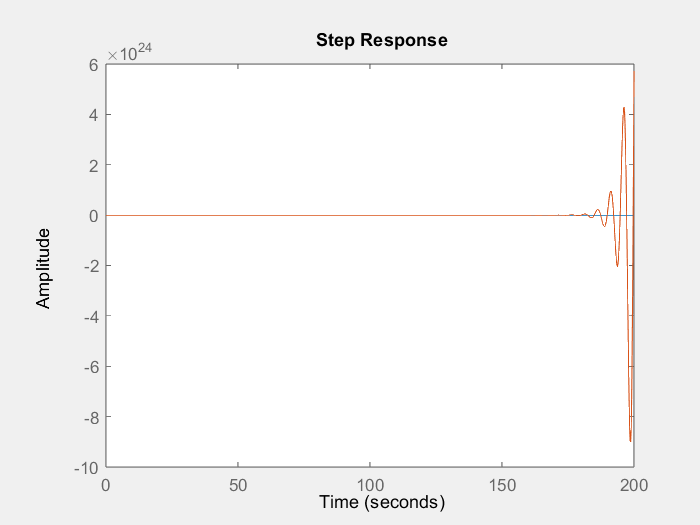

G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;
G2=tf([0 1],[x(1) x(2) x(3) x(4)]);
step(G1,G2);


b=G2.Numerator{1, 1};
a=G2.Denominator{1,1};
[z,p,k] =tf2zp(b,a);
disp('-----------------')

-----------------


disp('Bez ograniczen: ')
x1 = x(1)

x1 = 6.6845

x2 = x(2)

x2 = -5.7781

x3 = x(3)

x3 = 12.4918

x4 = x(4)

x4 = -2.9623

disp('-----------------')

function blad = ident(x)
%K = X0(1);
%T = X0(2);
%n = X0(3);

%a1=x(1);
%b2=x(2);

t=0:0.01:6;
G1=tf([0 1],[1 2 2.25 1.25]);
[G1p_Licz,G1p_Mian]=pade(0.5,3);
G1p=tf(G1p_Licz,G1p_Mian);
G1=G1*G1p;

G2=tf([0 1],[x(1) x(2) x(3) x(4)]);
[y1] = step(G1,t); % wzor
[y2] = step(G2,t); % dopasowanie

%---------------------------------------- ------%
% tutaj kod, który będzie obliczał
% odpowiedź skokową estymowanego modelu z optymalizacji
% o takiej samej długości jak odpowiedź
% obiektu rzeczywistego

% plot(t, y1);
% hold on;
% plot(t, y2);
% hold off;
% legend(["obiekt rzeczywisty", "obiekt estymowany"])
% title("Odpowiedź skokowa")
%---------------------------------------- ------%
e = y1-y2;
blad= sum(e.^2);
end